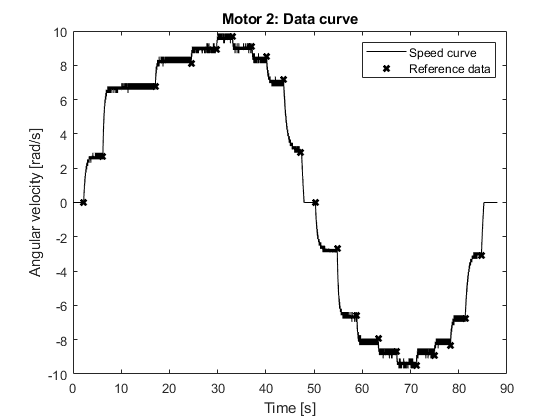

clear all
load Motor2

xlabel('Tiempo [s]')
ylabel('Velocidad [Rad/s]')
x=[];y=[];


x=[];y=[];
%primer"semiciclo"

%dinamica subida
x(1)=2.23;y0(1)=0;
x(2)=6.2;y0(2)=2.707;
x(3)=17.1;y0(3)=6.769;
x(4)=24.51;y0(4)=8.122;
x(5)=29.81;y0(5)=8.896;
%dinamica de bajada
x(6)=33.06;y0(6)=9.669;
x(7)=37.1;y0(7)=9.089;
x(8)=40.14;y0(8)=8.509;
x(9)=43.68;y0(9)=7.155;
x(10)=47.1;y0(10)=ControlOutput(x(10)/.005);

%segundo "semiciclo"

%dinamica bajada
x(11)=50.28;y0(11)=0;
x(12)=54.79;y0(12)=-2.707;
x(13)=58.87;y0(13)=-6.575;
x(14)=63.28;y0(14)=-7.929;
x(15)=67.17;y0(15)=-8.702;
%dinamica de subida
x(16)=71.2;y0(16)=-9.476;
x(17)=74.92;y0(17)=-8.896;
x(18)=78.28;y0(18)=-8.316;
x(19)=81.36;y0(19)=-6.769;
x(20)=84.69;y0(20)=-3.094;

plot (X_Value,ControlOutput,'k')
hold on
plot(x,y0,'xk','LineWidth',2)
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('Motor 2: Data curve')
legend('Speed curve','Reference data')
hold off



tamano=length(x)-1;
escalon=cell(tamano,2);
for i=1:tamano
    aux=(ControlOutput(x(i)/0.005));
    escalon{i,2}= ControlOutput(x(i)/0.005:x(i+1)/0.005)-aux;
    escalon{i,1}= linspace(0,x(i+1)-x(i),length(escalon{i,2}));
end
k=[];
Tao=[];
idx=[];
Funcion=cell(tamano,1);
Filtro=cell(tamano,1);

for i=1:tamano
    k(i)=mean(escalon{i,2}(end-100:end))-escalon{i,2}(1);
    [na,aux1]=min(abs(escalon{i,2}-0.63*k(i)));
    [na,aux2]=min(abs(escalon{i,2}-0.28*k(i)));
    Tao(i)=1.5*(escalon{i,1}(aux1)-escalon{i,1}(aux2));
    Funcion{i,1} = tf(k(i),[Tao(i),1]);
    
%     filtro
    Filtro{i,1} = tf(1,[Tao(i)/10,1]);
end

k, Tao

k =     2.7132    4.1052    1.5356    0.4691    0.7008   -0.6548   -0.5266   -1.3288   -3.9156   -2.9008   -2.8242   -3.9654   -1.5452   -0.4672   -0.4921    0.7046    0.5610    1.3729    3.5729


Tao =     0.3675    0.2325    0.1650    0.1200   -0.0075    0.0675    0.1650    0.1875    0.6000    0.2250    0.3900    0.2550    0.1350    0.1275    0.0150    0.0600    0.0900    0.1200    0.5325


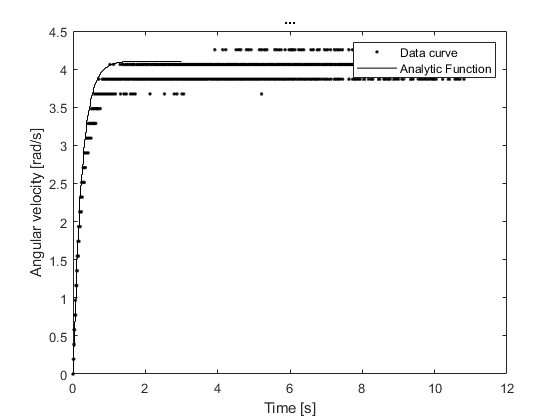

graficar=2;
plot(escalon{graficar,1},escalon{graficar,2},'.k')
hold on
[yAux,xAux]=step(Funcion{graficar},3);
stairs(xAux,yAux,'k')
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('...')
legend('Data curve','Analytic Function')
hold off


T=0.005;
% 

Filtrodigital=cell(tamano,1);
numfiltrodigital=zeros(tamano,1);
denfiltrodigital=zeros(tamano,1);

for i=1:tamano
    Filtrodigital{i,1} = c2d(Filtro{i,1},T);
    
    numfiltrodigital(i)=Filtrodigital{i}.num{1}(end);
    denfiltrodigital(i)=Filtrodigital{i}.den{1}(end);
end


aplicando el filtro

ecuacion en diferencias

y_k=num*x_k-1+den*y_k-1


Y=cell(tamano,1);

for j=1:tamano
y=[0];

aux1 = escalon{j,1};
aux2 = escalon{j,2};

for i=2:length(aux2) %para y valor actual comienza en 2
    y(i)=numfiltrodigital(j)*aux2(i-1)-denfiltrodigital(j)*y(i-1);
end

Y{j}=y;
end

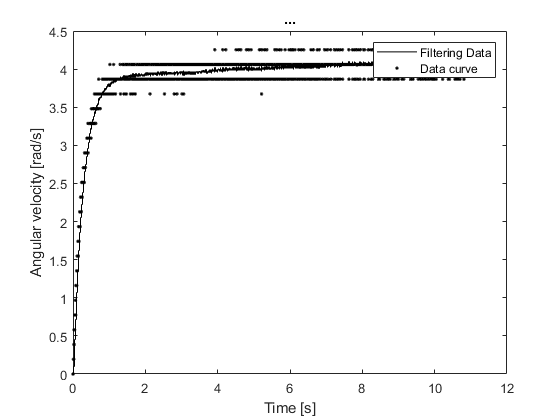


stairs(escalon{graficar,1},Y{graficar},'k')
hold on
plot(escalon{graficar,1},escalon{graficar,2},'.k')  % al aplicar el filtro se agrega un retardo
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('...')
legend('Filtering Data','Data curve')
hold off

Errores

Error2medio=(Y{graficar}'-escalon{graficar,2})'*(Y{graficar}'-escalon{graficar,2})/length(escalon{graficar,1})

Error2medio = 0.0144

 for i=1:tamano
    Error2medios(i)=(Y{i}'-escalon{i,2})'*(Y{i}'-escalon{i,2})/length(escalon{i,1});
 end
 Error2medios

Error2medios =     0.0120    0.0144    0.0155    0.0171       Inf    0.0192    0.0161    0.0158    0.0230    0.0061    0.0133    0.0198    0.0184    0.0181    0.0339    0.0242    0.0220    0.0199    0.0203
